# Midterm 1 Practice Probems with MATLAB

## Problem 2

**Sum of Random Variables**: Let 𝐴 and 𝐵 be independent random variables, with 𝐴 being normally distributed with mean 0 and variance 1, and 𝐵 being exponentially distributed with parameter 𝜆=2. Find the distribution of the sum 𝐴+𝐵

syms a b s
f_A(a) = 1/sqrt(2*pi) * exp(-1/2 * a^2)

$$f\_A(a) = \frac{7186705221432913\,{\mathrm{e}}^{-\frac{a^{2}}{2}}}{18014398509481984}$$

f_B(b) = piecewise(b < 0, 0 , b >= 0, 2*exp(-2*b))

$$f\_B(b) = \left\{ \begin{array}{cl} 0 & \text{ if }b<0\\ 2\,{\mathrm{e}}^{-2\,b} & \text{ if }0\leq b \end{array}\right.$$

f_S(s) = int(f_B(b)*f_A(s-b),b,-inf, inf)

$$f\_S(s) = \frac{7186705221432913\,\sqrt{2}\,\sqrt{\pi }\,{\mathrm{e}}^{-2\,s}\,{\mathrm{e}}^{2}\,\left(\mathrm{erf}\left(\frac{\sqrt{2}\,s}{2}-\sqrt{2}\right)+1\right)}{18014398509481984}$$

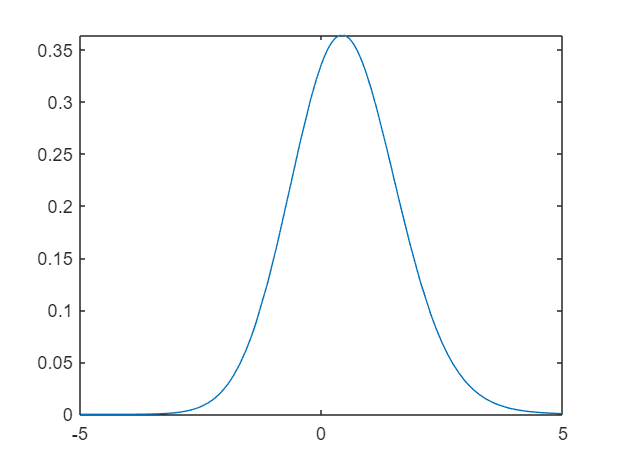

figure;
fplot(f_S)

figure;
fplot(exp(2-2*s)*(1 + erf((-2+s)/sqrt(2))))

sz = [9000, 1]

sz =         9000           1


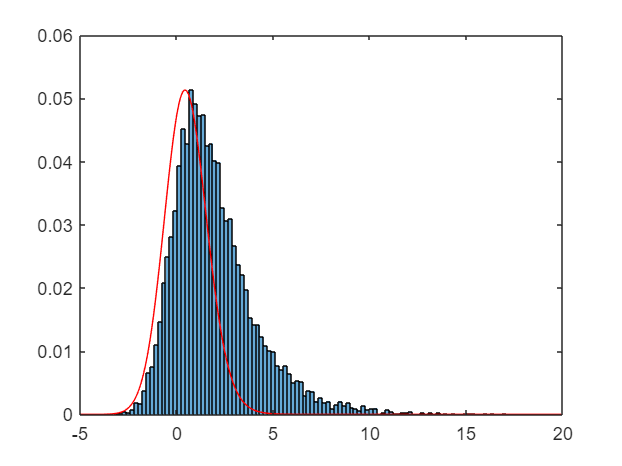

A = randn(sz);
B = exprnd(2,sz);
S = A + B;
figure;
h = histogram(S,100);
h.Normalization = 'probability';
hold on
x = -5:0.1:20;
pdfS = f_S(x);
% scale pdf to the height of the histogram:
pdfS = pdfS*max(h.Values)/max(pdfS);
plot(x,pdfS,'r')